# **Additive Schwarz and Restrictive Additive Schwarz**

#                    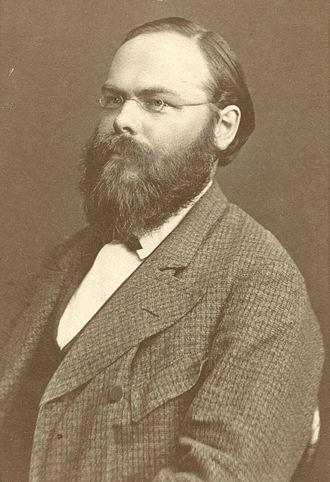 

[Simon Tavener](http://www.math.colostate.edu/~tavener) and Andre Leautaud

Full text can be found at the following [link](https://www.math.colostate.edu/~tavener/andre/DD_multiphysics.pdf)

#### Set path and output level

rehash path
addpath('DD_utilities','Additive_utilities','Restricted_Additive_utilities','Inputs')

iprint= 0;

% Create new system, solution strategies and perturbations or read from csv files
sread= true;
input_file= 'DD_param_andre';

% Write system, solution strategies and perturbations to csv files
swrite= false;
output_file= 'DD_param';


#### Establish and solve the forward system, Mx=y

#### Establish subdomains, partitions, number of iterations and random numerical error.  Read and/or save as appropriate

[n,p,K, alpha,nn,nb,ne,index, nnt,nbt,net,indext, M,y,xstore, mpert,wpert]= ...
    linear_system(sread,swrite,input_file,output_file);

Linear_system: Read linear system and solution strategy 



% Determine between additive and restricted additive Schwarz
restricted= false;
if restricted
    alpha= 1;
    fprintf('Restricted additive Schwarz \n')
end
fprintf('n= %4i, p= %4i, K= %4i, alpha= %13.4e, mpert= %10.4e \n\n', n, p, K, alpha, mpert)

n=   10, p=    4, K=    3, alpha=    5.0000e-01, mpert= 2.0000e-02 




% Ignore or respect accumulation of error in U iteration
accum= false;

if iprint >= 4
    fprintf('xstore \n')
    disp(xstore)
end

if iprint >= 6
    fprintf('M \n');
    disp(M)
    fprintf('y \n')
    disp(y)
end

#### Iterative strategy

$u^{\{k\}}= u^{\{k-1\}} + Br = u^{\{k-1\}} + B(f-Au^{\{k-1\}}), \quad k=1, \dots, K $ where $B$ is an approximation to $A^{-1}$

Additive


$$A_i= R_i A R_i^\top \in \mathbb{R}^{m_i \times m_i} \\
B_i= R_i^\top A_i^{-1} R_i  = R_i^\top ( R_i A R_i^\top)^{-1} R_i  \in \mathbb{R}^{n \times n} \\
C_i= B_i A   \in \mathbb{R}^{n \times n} \\
f_i= B_i f   \in \mathbb{R}^{n}
$$


Restricted Additive


$$A_i= R_i A R_i^\top \in \mathbb{R}^{m_i \times m_i} \\
\tilde{B_i}= \tilde{R_i}^\top A_i^{-1} R_i  = \tilde{R_i}^\top ( R_i A R_i^\top)^{-1} R_i  \in \mathbb{R}^{n \times n} \\
\tilde{C}_i= \tilde{B}_i A   \in \mathbb{R}^{n \times n} \\
\tilde{f}_i= \tilde{B}_i f   \in \mathbb{R}^{n}
$$


% Construct R and A matrices
R= Rmatrices(n,p,nn,index,iprint);
A= Amatrices(M,R,n,p,nn,iprint);

if restricted
    % Construct Rt and B matrices for RAS
    Rt= Rtmatrices(R,n,p,nn,nnt,index,indext,iprint);
    B= Btmatrices(A,R,Rt,n,p,nn,iprint);
else
    % Construct B matrix for AS
    B= Bmatrices(A,R,n,p,nn,iprint);
end

% Construct C matrices and f vectors
C= Cmatrices(M,B,n,p,iprint);
f= fvector(B,y,n,p,iprint);

#### $K$ iterations computing subdomain contributions independently [C iteration]

Additive Schwarz


$$u^{\{k\}}= u^{\{k-1\}} + \alpha \sum_{i=1}^p B_i (f-Au^{\{k-1\}}) = u^{\{k-1\}} + \alpha \sum_{i=1}^p ( f_i-C_i \, u^{\{k-1\}}) 
$$


Restricted Additive Schwarz


$$u^{\{k\}}= u^{\{k-1\}} + \sum_{i=1}^p \tilde{B}_i(f-Au^{\{k-1\}}) = u^{\{k-1\}} + \sum_{i=1}^p ( \tilde{f}_i-\tilde{C}_i \, u^{\{k-1\}}) $$


% Perform C iteration
vstore= Citeration_additive(C,f,alpha,n,p,K,iprint);
if iprint >= 4
    fprintf('vstore \n')
    disp(vstore')
end

#### $K$ iterations combining $p$ (parallel) subdomain solves [D iteration]

Additive Schwarz


$$u^{\{k\}}= D u^{\{k-1\}} + g, \qquad 
D = I-\alpha \sum_{i=1}^p C_i, \quad g= \alpha \sum_{i=1}^p f_i$$


Restricted Additive Schwarz


$$u^{\{k\}}= \tilde{D} u^{\{k-1\}} + \tilde{g}, \qquad
\tilde{D} = I-\alpha \sum_{i=1}^p \tilde{C}_i , \quad \tilde{g}= \alpha \sum_{i=1}^p \tilde{f}_i$$


% Perform D iteration
D= Dmatrix_additive(C,alpha,n,p,iprint);
g= gvector_additive(f,alpha,n,p,iprint);

wstore= Diteration_additive(D,g,n,p,K,iprint);

Diteration_additive: Asymptotic solution (asol)= inv(eye(n)-D)*g 
Diteration_additive: max(eig(D))=  5.381565e-01 
Diteration_additive: norm(w-asol)=  9.293539e-03 


if iprint >= 4
    fprintf('wstore \n')
    disp(wstore')
end


#### $K$ iterations as single matrix solve [U iteration]

$K=6$ iterations of additive Schwarz can be written as the $nK$-dimensional system of equations 

Additive Schwarz

    $Uz=
\pmatrix{
 I & 0 & 0 & 0 & 0 & 0   \cr
 -D &I & 0 & 0 & 0 & 0   \cr
 0 & -D & I & 0 & 0 & 0   \cr
 0 & 0 & -D & I & 0 & 0   \cr
 0 & 0 & 0 & -D & I & 0   \cr
 0 & 0 & 0 & 0 & -D & I
}

\pmatrix{
v^{\{1\}}  \cr
v^{\{2\}}  \cr
v^{\{3\}}  \cr
v^{\{4\}}  \cr
v^{\{5\}}  \cr
v^{\{6\}}
}
=
\pmatrix{
g  \cr
g  \cr
g  \cr
g  \cr
g  \cr
g
}
=h$. 

Restricted Additive Schwarz

   
$$\tilde{U}z=
\pmatrix{
 I & 0 & 0 & 0 & 0 & 0   \cr
 -\tilde{D} &I & 0 & 0 & 0 & 0   \cr
 0 & -\tilde{D}  & I & 0 & 0 & 0   \cr
 0 & 0 & -\tilde{D}  & I & 0 & 0   \cr
 0 & 0 & 0 & -\tilde{D}  & I & 0   \cr
 0 & 0 & 0 & 0 & -\tilde{D}  & I
}

\pmatrix{
v^{\{1\}}  \cr
v^{\{2\}}  \cr
v^{\{3\}}  \cr
v^{\{4\}}  \cr
v^{\{5\}}  \cr
v^{\{6\}}
}
=
\pmatrix{
\tilde{g}  \cr
\tilde{g}   \cr
\tilde{g}   \cr
\tilde{g}   \cr
\tilde{g}   \cr
\tilde{g} 
}
=\tilde{h} $$


%  Perform U iteration
U= Umatrix_additive(D,n,K,iprint);
h= hvector_additive(g,n,K,iprint);

zstore= Uhsolve_additive(U,h,n,K,iprint);
if iprint >= 4
    fprintf('zstore \n')
    disp(zstore')
end

#### Compare solutions from all three methods

solution_compare(xstore,vstore((K-1)*n+1:n*K),vstore,wstore,zstore,iprint)


Comparing solutions 
norm(exact-iterative) =  9.293539e-03 
norm(vstore-wstore)   =  2.549512e-17 
norm(wstore-zstore)   =  3.638787e-17 
norm(vstore-zstore)   =  3.254630e-17 


## Add discretization error and compute error estimate

### C iteration with error

psi= ones(n,1);
fprintf('\nPerforming C iteration with error \n')


Performing C iteration with error 



% Solve system with "numerical error" for every solve
[vglobal_store,vaglobal_store,rglobal_store]= Citeration_additive_approx(C,f,alpha,n,p,K,mpert,wpert,iprint);
if iprint >= 4
    fprintf('vglobal_store \n')
    disp(vglobal_store')
    fprintf('vaglobal_store \n')
    disp(vaglobal_store')
    fprintf('rglobal_store \n')
    disp(rglobal_store')
end

#### *Calculate the discretization error and effectivity ratio*

% Adjoint solve
[phiglobal_store]= Citeration_additive_adjoint(C,psi,alpha,n,p,K,iprint);
if iprint >= 4
    fprintf('phiglobal_store \n')
    disp(phiglobal_store')
end

% Error estimate= (r,\phi)
qoi_discretization_error_estimate= rglobal_store'* phiglobal_store;
if iprint >= 4
    fprintf('norm(r_store) = %13.6e, norm(phi_store)= %13.6e \n', norm(rglobal_store), norm(phiglobal_store))
end

% Compute error and error in QoI directly
vsoln= vglobal_store(n*(K-1)+1:n*K,1);
vasoln= vaglobal_store(n*K+1:n*(K+1),1);
verror= vsoln-vasoln;
qoi_discretization_error= psi'*verror;

% Calculate effectivity ratio
effectivity_ratio_disc= qoi_discretization_error_estimate/qoi_discretization_error;
fprintf('QoI_discretization_error          = %13.6e \n', qoi_discretization_error)

QoI_discretization_error          = -1.242586e-01 


fprintf('QoI_discretization_error_estimate = %13.6e \n', qoi_discretization_error_estimate)

QoI_discretization_error_estimate = -1.242586e-01 


fprintf('Effectivity ratio                 = %13.3f \n', effectivity_ratio_disc)

Effectivity ratio                 =         1.000 


#### *Calculate the total error and effectivity ratio*

% Adjoint solve
phi= M'\psi;

% Residual
r= y-M*vasoln;

% Error estimate= (r,\phi)
qoi_total_error_estimate= r'*phi;

% Compute error in QoI directly
total_error= xstore-vasoln;
qoi_total_error= psi'*total_error;

% Calculate effectivity ratio
effectivity_ratio_total= qoi_total_error_estimate/qoi_total_error;
fprintf('QoI_total_error                   = %13.6e \n', qoi_total_error)

QoI_total_error                   = -1.185734e-01 


fprintf('QoI_total_error_estimate          = %13.6e \n', qoi_total_error_estimate)

QoI_total_error_estimate          = -1.185734e-01 


fprintf('Effectivity ratio                 = %13.3f \n', effectivity_ratio_total)

Effectivity ratio                 =         1.000 


#### *Calculate the iteration error as the difference between the total error and the discretization error*

qoi_iteration_error= qoi_total_error-qoi_discretization_error;
fprintf('QoI_iteration_error               = %13.6e \n\n', qoi_iteration_error)

QoI_iteration_error               =  5.685275e-03 



#### D iteration with error

% Diteration with error (check summing of errors during a single "sweep")
% fprintf('Perform D iteration with error \n')
% [w_store,wa_store,wr_store]= Diteration_additive_approx(D,g,alpha,n,p,K,mpert,wpert,iprint);
% fprintf('norm(w_store-vglobal_store)  = %13.6e \n', norm(w_store-vglobal_store))
% fprintf('norm(wa_store-vaglobal_store)= %13.6e \n', norm(wa_store-vaglobal_store))
% fprintf('norm(wr_store-rglobal_store) = %13.6e \n', norm(wr_store-rglobal_store))


### U iteration with error

fprintf('\nSolving U system with error \n')


Solving U system with error 


if accum
    fprintf('Respecting error accumulation \n')
    [zexact,zapprox,zresid]= Uhsolve_additive_approx_accum(U,D,h,n,p,K,alpha,mpert,wpert,iprint);
else
    fprintf('Ignoring error accumulation \n')
    [zexact,zapprox,zresid]= Uhsolve_additive_approx(U,h,n,p,K,alpha,mpert,wpert,iprint);
end

Ignoring error accumulation 



if iprint >= 4
    fprintf('zexact \n')
    disp(zexact')
    fprintf('zapprox \n')
    disp(zapprox')
    fprintf('zresid \n')
    disp(zresid')
end

#### *Calculate the discretization error and effectivity ratio*


% Adjoint data (Adjoint system is of size nK)
psi_nK= zeros(n*K,1);
psi_nK(n*(K-1)+1:n*K,1)= psi;

% Solve adjoint equation
phi_nK= U'\psi_nK;
if iprint >= 2
    fprintf('Norm of difference between phi_nK and phiglobal_store = %13.6e \n', norm(phi_nK-phiglobal_store))
end

% Compute error estimate
qoi_discretization_error_estimate= phi_nK'*zresid;

% Compute error and error in QoI directly
zsoln= zexact(n*(K-1)+1:n*K,1);
zasoln= zapprox(n*(K-1)+1:n*K,1);
zerror= zsoln-zasoln;
qoi_discretization_error= psi'*zerror;

% Calculate effectivity ratio
effectivity_ratio_disc= qoi_discretization_error_estimate/qoi_discretization_error;
fprintf('QoI_discretization_error_estimate = %13.6e \n', qoi_discretization_error_estimate)

QoI_discretization_error_estimate = -1.158458e-01 


fprintf('QoI_discretization_error          = %13.6e \n', qoi_discretization_error)

QoI_discretization_error          = -1.158458e-01 


fprintf('Effectivity ratio                 = %13.3f \n', effectivity_ratio_disc)

Effectivity ratio                 =         1.000 


#### *Calculate the total error and effectivity ratio*

% Residual
r= y-M*zasoln;

% Error estimate= (r,\phi)
qoi_total_error_estimate= r'*phi;

% Compute error in QoI directly
total_error= xstore-zasoln;
qoi_total_error= psi'*total_error;

% Effectivity ratio
effectivity_ratio_total= qoi_total_error_estimate/qoi_total_error;
fprintf('QoI_total_error                   = %13.6e \n', qoi_total_error)

QoI_total_error                   = -1.101605e-01 


fprintf('QoI_total_error_estimate          = %13.6e \n', qoi_total_error_estimate)

QoI_total_error_estimate          = -1.101605e-01 


fprintf('Effectivity ratio                 = %13.3f \n', effectivity_ratio_total)

Effectivity ratio                 =         1.000 


#### *Calculate the iteration error as the difference between the total error and the discretization error*

qoi_iteration_error= qoi_total_error-qoi_discretization_error;
fprintf('QoI_iteration_error               = %13.6e \n', qoi_iteration_error)

QoI_iteration_error               =  5.685275e-03 
